# Underactuated Control Tuning:

The goal of this live script is to test and do the final tuning of the underactuated control scheme developed in P2CS1. Note that the attitude controller is simplified as explained in its tuning live script. Preliminary tuning of the position and attitude controllers is done independently via linearized models. This live script interacts with a Simulink model that represents the coupled dynamics of the platform with the intention of validating the architecture and finalizing the tuning of the controllers. 

The control objective is related to step changes in position in each axis independently (easier to manage), where the goal is to respond like a second order system with $\omega_n=10 \; rad/s$ and $\zeta =0.9$, (values taken from ACS project 2025 -> See Robust Linear Control with H-infinity synthesis project). Note that the goals are preliminary, they might be adjusted if they prove out of the system's reach. 

addpath("Models and Auxiliary Functions\")

## Model Definition and Initialization: 

A model this large and complex requires lots of definitions and initializations. The goal of this section is to handle these independently, save for the desired trajectory. This last point is left for another section to make this section modular, easing its translation into other scripts. Furthermore, definitions and initialization are handled separately and subsystem by subsystem, to make them easier to follow. A parameter is "defined" when its value is set and is not expected to vary when the model is used for other tasks (i.e. mass,...). On the other hand, it is "initialized" when it is expected to change in different simulations (i.e. initial conditions, propeller efficiencies,...).

#### Definitions: 

First, let's define all parameters relevant to the UAV dynamics themselves, excluding actuators. 

%Specify gravitational acceleration: 
g=9.81; %[m/s^2]

%Geometric and Inertial Properties:
UAV.Nr = 6; %number of rotors
UAV.m = 1.2; %[kg] UAV mass
UAV.J = diag([0.01 0.01 0.018]); % [kg m^2] inertia matrix
UAV.r_bg = [0 0 0]'; %[m] center of mass location in the body frame -> note I change it to a column vector. 
UAV.S = UAV.m*cross_matrix(UAV.r_bg); % [kg m] static moment
UAV.MM=[UAV.m*eye(3,3),UAV.S';UAV.S,UAV.J];
UAV.MM_inv=inv(UAV.MM);

% Linear Aerodynamics
UAV.D_tauomega = diag([0.48 0.48 2.37]); %  angular velocity damping 
UAV.D_fv =  diag([0.055 0.055 0.022]); % linear velocity damping
UAV.D = [UAV.D_fv zeros(3,3); zeros(3,3) UAV.D_tauomega]; %-> there is a typo in the position of D_fv and D_tauomega on the data provided by the professor

% Propellers 
UAV.b = 0.215; %[m] arm length (ell in the slides)

k_f = 3.65e-6;                % [N/rad^2/s^2] Thrust characteristic coeff
sigma = 0.09;                 % [m] Torque-to-thrust ratio

%Construct input map:
%Rotors 1,3,5 rotate in the positive direction, 2,4,6 rotate in the
%negative direction
xiv=zeros(UAV.Nr,1);
xiv(1:2:UAV.Nr)=1; 
xiv(2:2:UAV.Nr)=-1;

gamma_r=2*pi/UAV.Nr*(0:UAV.Nr-1);
nr=[0;0;1];

F=nan(6,UAV.Nr);
for i=1:UAV.Nr
    pr=UAV.b*[cos(gamma_r(i));sin(gamma_r(i));0];
    pr_x=cross_matrix(pr);
    F(1:3,i)=nr;
    F(4:6,i)=(pr_x-xiv(i)*sigma*eye(3,3))*nr;
end

UAV.F=F;

Now, let's define the parameters relevant for actuator dynamics. Note I leave the Lambda Matrix for the initialization phase.  

UAV.Omega_max = 10300; %[rpm] max spinning rate
UAV.Omega_min = 1260; %[rpm] min spinning rate
UAV.k_m = 1/0.05; % [s-1] Inverse of the time constant of the propeller motors

T_max=k_f*(UAV.Omega_max*2*pi/60)^2; %Unit conversion needed since kf is in N/(rad^2/s^2) and Omega_max and _min are given in rpm.
T_min=k_f*(UAV.Omega_min*2*pi/60)^2;

Proceed with the definitions necessary for the baseline controller. Note that controller gains will be initialized later. 

%For control allocation: (validated expression for F2 Plus)
F_2=F(3:6,:);
UAV.F_2_Plus=F_2'/(F_2*F_2');

## Controller Tuning: 

Based on the schemes developed and tested in simplified models, this section defines the controller gains: 

%Define position controller: 
%Performance Goals: 
omega_n_p=10; %[rad/s]
zeta_p=0.9;    %[-]

%Convert to tuning: 
kp=omega_n_p^2;
kv=2*zeta_p*omega_n_p;

K_p=kp*eye(3,3);
K_v=kv*eye(3,3);

%Define attitude controller: 
%Tune controller: 
omega_n_a=20; %[rad/s]
zeta_a=1;     %[-]

%Tune k_r
k_r_hat=omega_n_a^2*diag(UAV.J);
A=[0,1,1;1,0,1;1,1,0];
k_r=A\k_r_hat;

%Tune K_omega:
K_omega=2*zeta_a*omega_n_a*UAV.J;

## Case 1: Step in x direction

In this case, we study the response of the system to a 1 meter step in the x direction. We assume that all propellers are working nominally and compare the results with those of the reference system. 

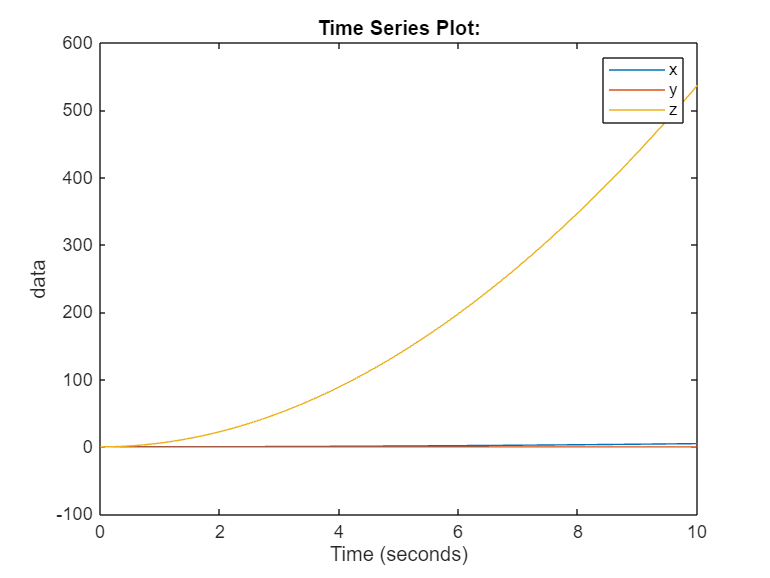

%Define Lambda:
Lambda=eye(6,6);
%Define desired position:
p_d=[1;0;0]; %[m]

%Initialize system: consider it starting from a trim condition at [0;0;0]
%Initialize postion and kinematics: 
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];
v_b_0=[0;0;0];
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];

%Initialize rotor angular velocities: 
T_0=UAV.m*g/UAV.Nr; 
Omega_r_0=sqrt(T_0/k_f)*ones(UAV.Nr,1);

%Simulate system response: 
simout=sim("UC_Step_Response.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_b_i)
legend('x','y','z')

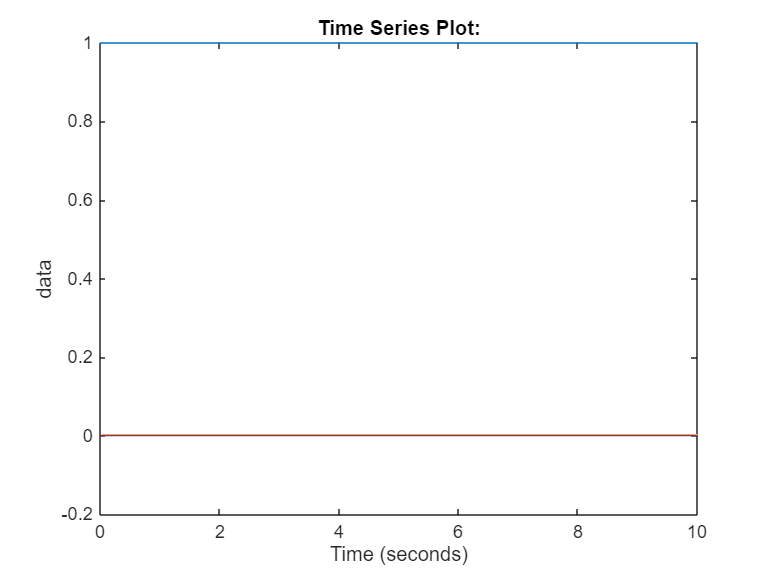

%Plot attitude: 
figure
clf
plot(simout.q)

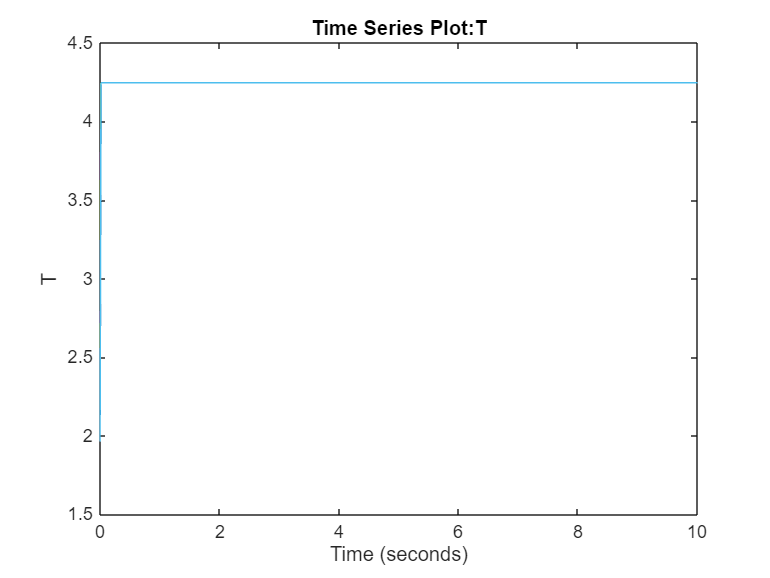

%Plot required controls:
figure 
clf 
plot(simout.Tr)

## Testing of updated controller: x step 

After the atrocious results in the first test, I understand the failure mechanism. Essentially, the objective I chose for the system initially greatly exceeds its actuation capabilities. Therefore, from the get go all actuators are saturated. This means that there is no way to change attitude, so the drone just shoots up into the sky. This increases the error in position, so the position controller demands a higher overall thrust to change attitude and is locked in by saturation. In light of this issue, I must reduce the system performance requirements and try again. Some strategy to mitigate saturation issues could be very interesting as well. We have not studied these in detail however, so I will avoid them for the time being. Let's retune the controllers and see what we can get: 

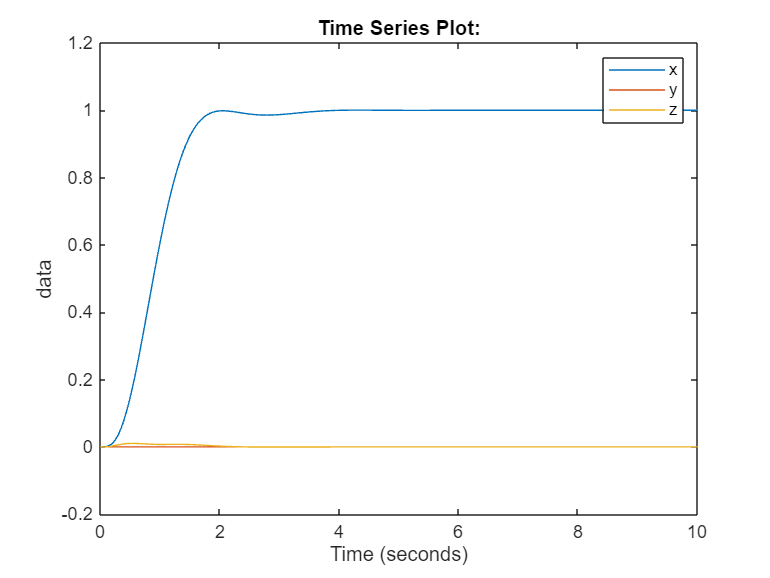

%Define position controller: 
%Performance Goals: 
omega_n_p=1.75; %[rad/s]
zeta_p=0.8;    %[-]

%Convert to tuning: 
kp=omega_n_p^2;
kv=2*zeta_p*omega_n_p;

K_p=kp*eye(3,3);
K_v=kv*eye(3,3);

%Define attitude controller: 
%Tune controller: 
omega_n_a=20; %[rad/s]
zeta_a=1;     %[-]

%Tune k_r
k_r_hat=omega_n_a^2*diag(UAV.J);
A=[0,1,1;1,0,1;1,1,0];
k_r=A\k_r_hat;

%Tune K_omega:
K_omega=2*zeta_a*omega_n_a*UAV.J;

%Try simulation once again:
%Define Lambda:
Lambda=eye(6,6);
%Define desired position:
p_d=[1;0;0]; %[m]

%Initialize system: consider it starting from a trim condition at [0;0;0]
%Initialize postion and kinematics: 
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];
v_b_0=[0;0;0];
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];

%Initialize rotor angular velocities: 
T_0=UAV.m*g/UAV.Nr; 
Omega_r_0=sqrt(T_0/k_f)*ones(UAV.Nr,1);

%Simulate system response: 
simout=sim("UC_Step_Response.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_b_i)
legend('x','y','z')

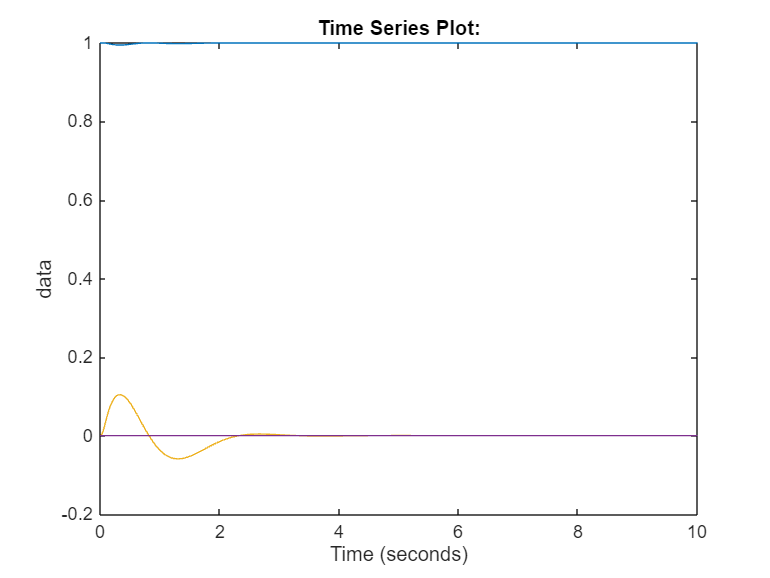

%Plot attitude: 
figure
clf
plot(simout.q)

Interestingly enough, by relaxing overshoot restrictions on position and increasing the frequency of the attitude controller up to the system's bandwidth, it is possible to obtain a significantly faster system I am much happier with. The best way to conclude this test will be to contrast the system's response in x to that of the reference model. Then, I will test the remaining axes to validate this initial controller specification. 

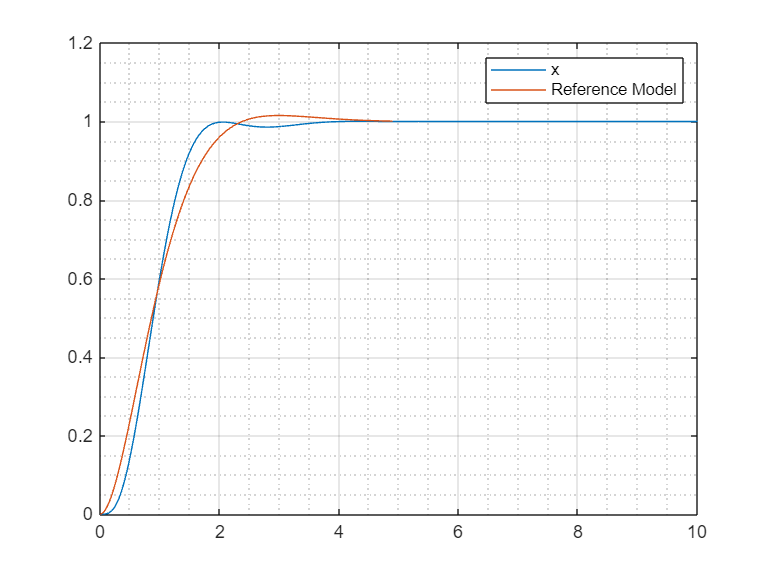

x_data=nan(size(simout.p_b_i.time));
for i=1:length(simout.p_b_i.time)
    x_data(i)=simout.p_b_i.data(1,1,i);
end

%Reference model response: 
s=tf('s');
G=omega_n_p^2/(s^2+2*zeta_p*omega_n_p*s+omega_n_p^2);
[x_ref,t_ref]=step(G);

figure
clf
plot(simout.p_b_i.time,x_data,'DisplayName','x')
hold on
plot(t_ref,x_ref,'DisplayName','Reference Model')
grid on 
grid minor
legend()

We can see some excellent agreement between the controller implementation and the reference model! We can be happy with this implementation then. Let's proceed with the remaining axes. 

## New controller, y step: 

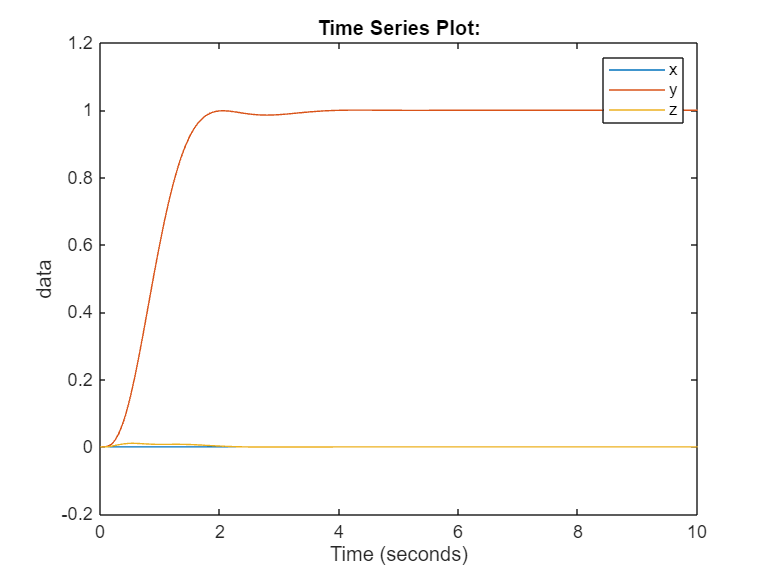

%Define position controller: 
%Performance Goals: 
omega_n_p=1.75; %[rad/s]
zeta_p=0.8;    %[-]

%Convert to tuning: 
kp=omega_n_p^2;
kv=2*zeta_p*omega_n_p;

K_p=kp*eye(3,3);
K_v=kv*eye(3,3);

%Define attitude controller: 
%Tune controller: 
omega_n_a=20; %[rad/s]
zeta_a=1;     %[-]

%Tune k_r
k_r_hat=omega_n_a^2*diag(UAV.J);
A=[0,1,1;1,0,1;1,1,0];
k_r=A\k_r_hat;

%Tune K_omega:
K_omega=2*zeta_a*omega_n_a*UAV.J;

%Try simulation once again:
%Define Lambda:
Lambda=eye(6,6);
%Define desired position:
p_d=[0;1;0]; %[m]

%Initialize system: consider it starting from a trim condition at [0;0;0]
%Initialize postion and kinematics: 
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];
v_b_0=[0;0;0];
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];

%Initialize rotor angular velocities: 
T_0=UAV.m*g/UAV.Nr; 
Omega_r_0=sqrt(T_0/k_f)*ones(UAV.Nr,1);

%Simulate system response: 
simout=sim("UC_Step_Response.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_b_i)
legend('x','y','z')

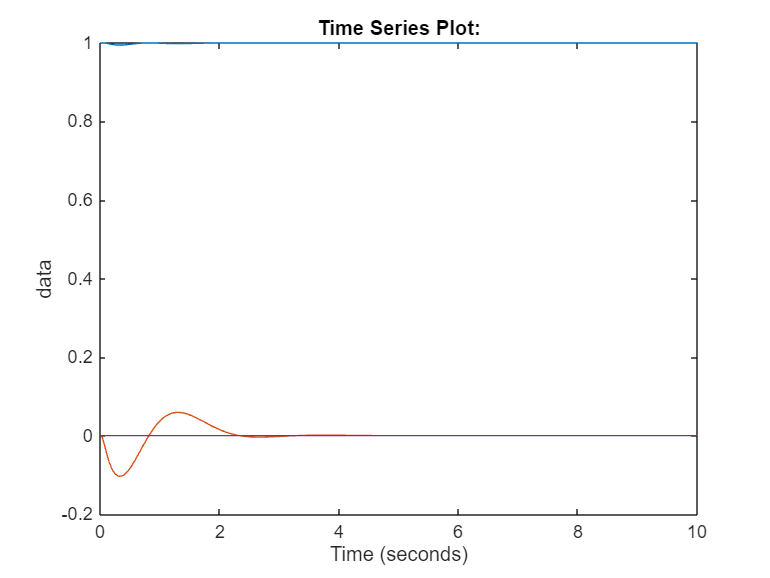


%Plot attitude: 
figure
clf
plot(simout.q)

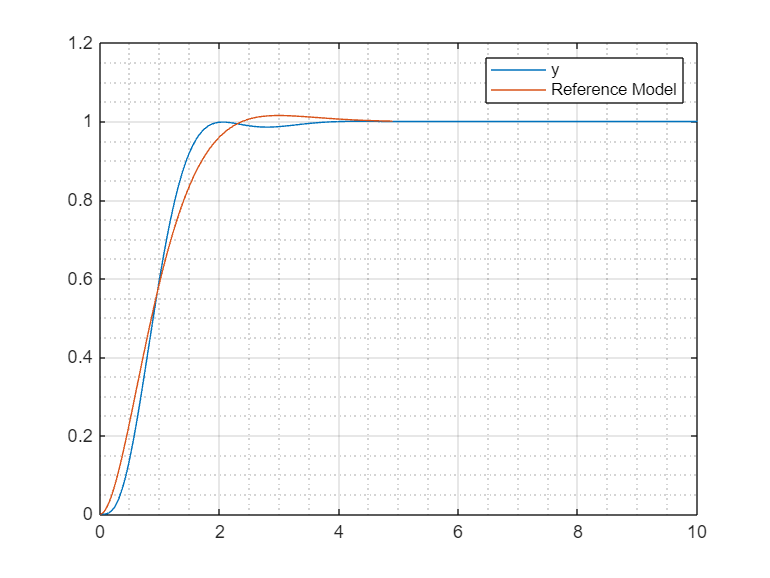


y_data=nan(size(simout.p_b_i.time));
for i=1:length(simout.p_b_i.time)
    y_data(i)=simout.p_b_i.data(2,1,i);
end

%Reference model response: 
s=tf('s');
G=omega_n_p^2/(s^2+2*zeta_p*omega_n_p*s+omega_n_p^2);
[y_ref,t_ref]=step(G);

figure
clf
plot(simout.p_b_i.time,y_data,'DisplayName','y')
hold on
plot(t_ref,y_ref,'DisplayName','Reference Model')
grid on 
grid minor
legend()

Once again, a very nice and promising result from this axis. Let us now test the last one.

## New controller, z step: 

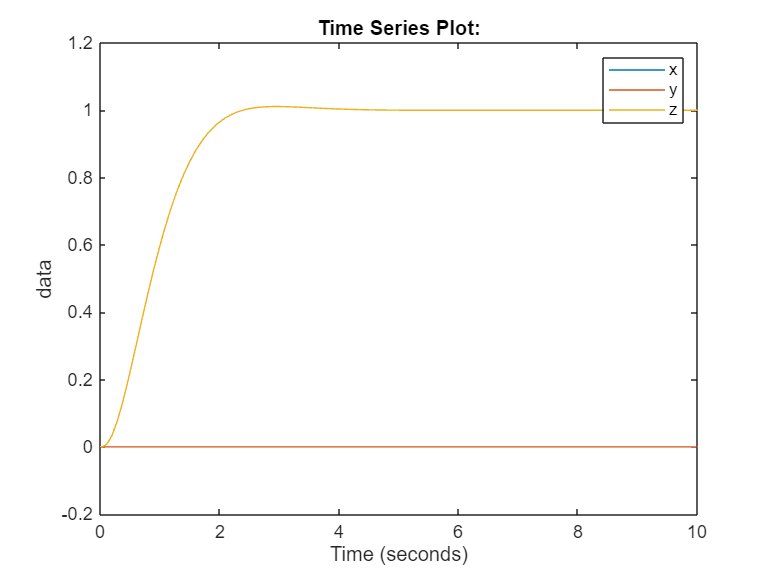

%Define position controller: 
%Performance Goals: 
omega_n_p=1.75; %[rad/s]
zeta_p=0.8;    %[-]

%Convert to tuning: 
kp=omega_n_p^2;
kv=2*zeta_p*omega_n_p;

K_p=kp*eye(3,3);
K_v=kv*eye(3,3);

%Define attitude controller: 
%Tune controller: 
omega_n_a=20; %[rad/s]
zeta_a=1;     %[-]

%Tune k_r
k_r_hat=omega_n_a^2*diag(UAV.J);
A=[0,1,1;1,0,1;1,1,0];
k_r=A\k_r_hat;

%Tune K_omega:
K_omega=2*zeta_a*omega_n_a*UAV.J;

%Try simulation once again:
%Define Lambda:
Lambda=eye(6,6);
%Define desired position:
p_d=[0;0;1]; %[m]

%Initialize system: consider it starting from a trim condition at [0;0;0]
%Initialize postion and kinematics: 
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];
v_b_0=[0;0;0];
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];

%Initialize rotor angular velocities: 
T_0=UAV.m*g/UAV.Nr; 
Omega_r_0=sqrt(T_0/k_f)*ones(UAV.Nr,1);

%Simulate system response: 
simout=sim("UC_Step_Response.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_b_i)
legend('x','y','z')

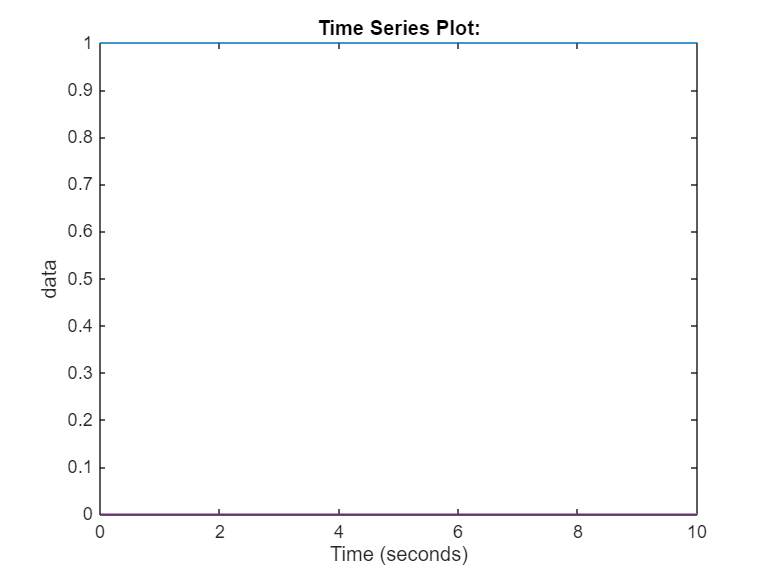


%Plot attitude: 
figure
clf
plot(simout.q)

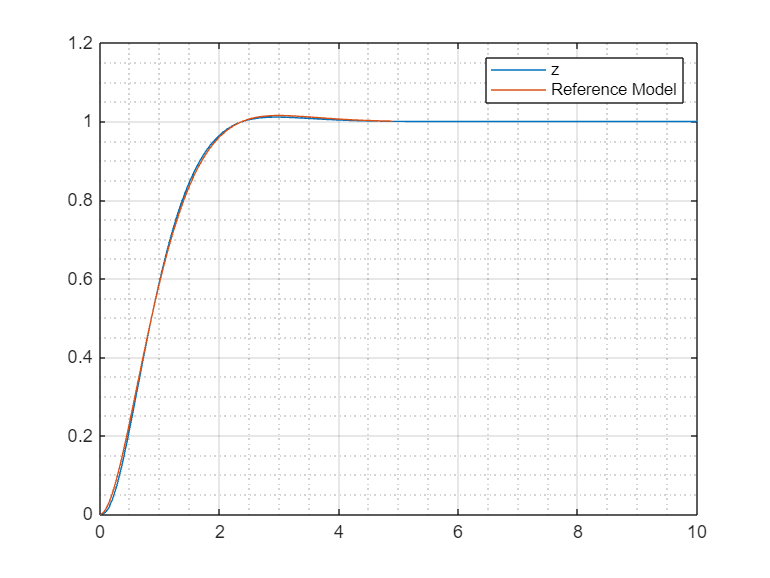


z_data=nan(size(simout.p_b_i.time));
for i=1:length(simout.p_b_i.time)
    z_data(i)=simout.p_b_i.data(3,1,i);
end

%Reference model response: 
s=tf('s');
G=omega_n_p^2/(s^2+2*zeta_p*omega_n_p*s+omega_n_p^2);
[z_ref,t_ref]=step(G);

figure
clf
plot(simout.p_b_i.time,z_data,'DisplayName','z')
hold on
plot(t_ref,y_ref,'DisplayName','Reference Model')
grid on 
grid minor
legend()

Perfect! I can also see how there is no variation in x or y since the vehicle does not need to change its attitude to change positions. I can thus be quite happy with the implementation. 

## Conclusions: 

This section began with a preliminary set of performance requirements that proved incompatible with the system's actuators. In essence, it was too aggressive for the thrust range available to the UAV's propellers. Leveraging the physical meaning of the inputs to the controller tuning algorithm, I played around a bit until I found some reasonable performance requirements that could be met by the system. These were then tested in all axes. As a result, we now have a preliminary controller. To close task 2, we will just test this controller in a more elaborate trajectory.